%例6-1串联超前校正
num=20;  den=[0.5 1 0];
w=logspace(-1,2,500);
sysk=tf(num,den)


sysk =
 
      20
  -----------
  0.5 s^2 + s
 
Continuous-time transfer function.



[mag,phase,w]=bode(sysk,w);
[Gm,Pm,Wcg,Wcp]=margin(mag,phase,w);
Phi1=(45-Pm+5)*pi/180;
alpha=(1-sin(Phi1))/(1+sin(Phi1));
M=10*log10(alpha)*ones(length(w),1);
semilogx(w,20*log10(mag(:)),w,M)
wmmin=w(20*log10(mag(:))>M);wmin=max(wmmin);
wmmax=w(20*log10(mag(:))<M);wmax=min(wmmax);
wm=(wmin+wmax)/2;
wc=wm;
T=1/sqrt(alpha)/wc;
alphaT=alpha*T;
numx=[T 1];denx=[alphaT 1];
sysx=tf(numx,denx);
[numx,dens]=series(numx,denx,num,den);
syss=tf(numx,dens)


syss =
 
          4.333 s + 20
  ----------------------------
  0.03323 s^3 + 0.5665 s^2 + s
 
Continuous-time transfer function.



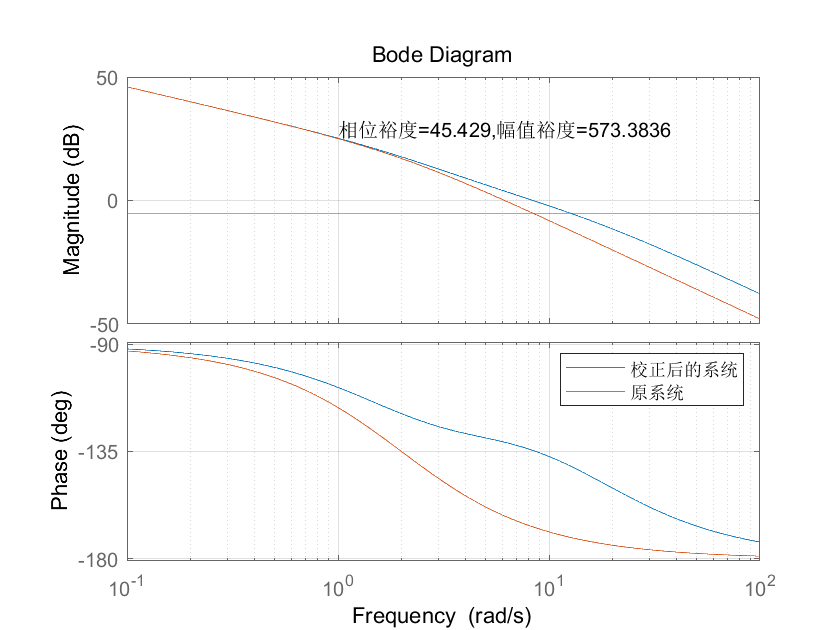

[mag,phase,w]=bode(syss,w);
[Gm,Pm,Wcg,Wcp]=margin(mag,phase,w);
hold on;
bode(tf(syss),w);
bode(tf(sysk),w);
hold off;
grid;
text(1,0,['相位裕度=',num2str(Pm),',幅值裕度=',num2str(Gm)])
legend('校正后的系统','原系统')

%例6-2串联超前校正
num=40;  den=[1 2 0];
w=logspace(-1,2,500);
sysk=tf(num,den)


sysk =
 
     20
  ---------
  s^2 + 2 s
 
Continuous-time transfer function.



[mag,phase,w]=bode(sysk,w);
[Gm,Pm,Wcg,Wcp]=margin(mag,phase,w);
Phi1=(45-Pm+5)*pi/180;
alpha=(1-sin(Phi1))/(1+sin(Phi1));
M=10*log10(alpha)*ones(length(w),1);
semilogx(w,20*log10(mag(:)),w,M)
wmmin=w(20*log10(mag(:))>M);wmin=max(wmmin);
wmmax=w(20*log10(mag(:))<M);wmax=min(wmmax);
wm=(wmin+wmax)/2;wc=wm;
T=1/sqrt(alpha)/wc;
alphaT=alpha*T;
numx=[T 1];denx=[alphaT 1];
sysx=tf(numx,denx);
[nums,dens]=series(numx,denx,num,den);
syss=tf(nums,dens)


syss =
 
          5.766 s + 20
  ----------------------------
  0.1178 s^3 + 1.236 s^2 + 2 s
 
Continuous-time transfer function.



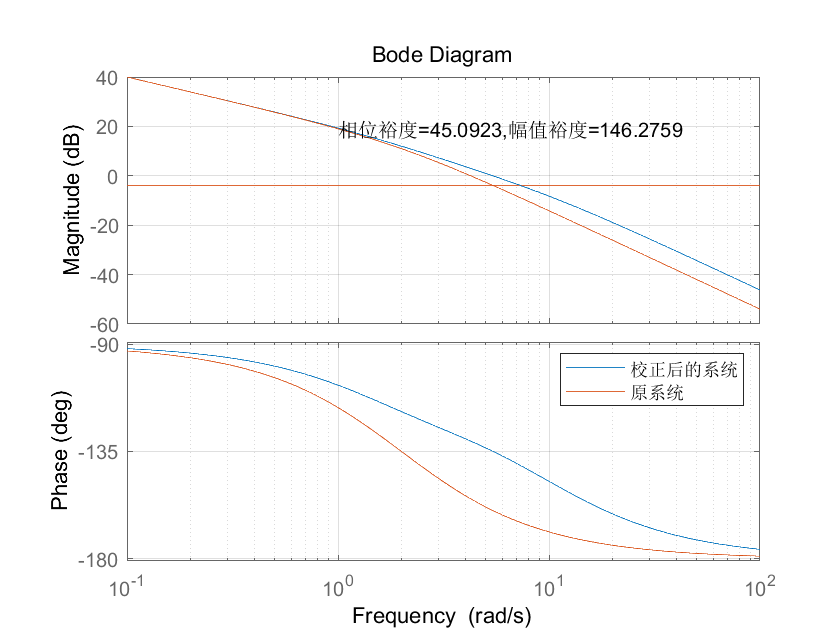

[mag,phase,w]=bode(syss,w);
[Gm,Pm,Wcg,Wcp]=margin(mag,phase,w);
hold on;bode(tf(syss),w);bode(tf(sysk),w);hold off;grid on;
text(1,0,['相位裕度=',num2str(Pm),',幅值裕度=',num2str(20*log10(Gm))])
legend('校正后的系统','原系统')

%例6-3串联滞后校正
ess=0.2;k=1/ess; num=k;  den=conv([1 1 0],[0.5 1]);
w=logspace(-2,1,500);
sysk=tf(num,den);


sysk =
 
            5
  ---------------------
  0.5 s^3 + 1.5 s^2 + s
 
Continuous-time transfer function.



[mag,phase,w]=bode(sysk,w);
[Gm,Pm,Wcg,Wcp]=margin(mag,phase,w);
Phi1=(-180+40+10)*ones(length(w),1);
wmmin=w(phase(:)>Phi1);wmin=max(wmmin);
wmmax=w(phase(:)<Phi1);wmax=min(wmmax);
wm=(wmin+wmax)/2;wc=wm;
wt=wc/5;T=1/wt; beita=10;
beitaT=beita*T;
numx=[T 1];denx=[beitaT 1];
sysx=tf(numx,denx);


sysx =
 
  10.15 s + 1
  -----------
  101.5 s + 1
 
Continuous-time transfer function.



[nums,dens]=series(numx,denx,num,den);
syss=tf(nums,dens);


syss =
 
              50.76 s + 5
  -----------------------------------
  50.76 s^4 + 152.8 s^3 + 103 s^2 + s
 
Continuous-time transfer function.



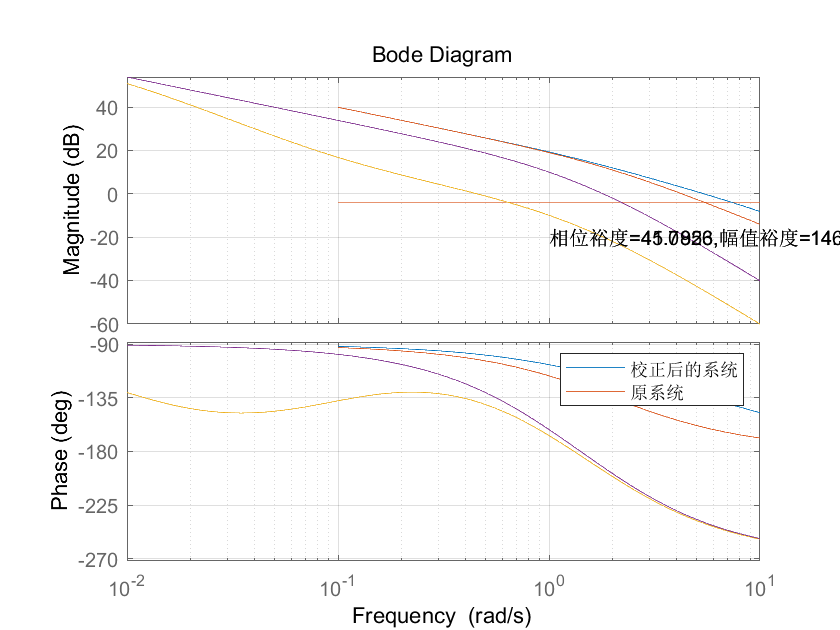

[mag,phase,w]=bode(syss,w);
[Gm,Pm,Wcg,Wcp]=margin(mag,phase,w);
hold on;bode(tf(syss),w);bode(tf(sysk),w);hold off;grid on;
text(0.1,0,['相位裕度=',num2str(Pm),',幅值裕度=',num2str(20*log10(Gm))])
legend('校正后的系统','原系统')

%例6-4串联相位滞后-超前校正
ess=0.1;k=1/ess; num=k;  den=conv([1 1 0],[0.5 1]);
w=logspace(-2,1,500);
sysk=tf(num,den);
[mag,phase,w]=bode(sysk,w);
[Gm,Pm,Wcg,Wcp]=margin(mag,phase,w);
Phi1=(40-Pm+5)*pi/180;
alpha=(1-sin(Phi1))/(1+sin(Phi1));
wc=Wcg;
Phi2=(-180+40+10)*ones(length(w),1);
wt2=wc/10;
T2=1/wt2;beita=10;beitaT2=beita*T2;
num2=[T2 1];den2=[beitaT2 1];sys2=tf(num2,den2);
wt=10^(13/20*(log10(15)-log10(1.5))+log10(1.5));
wt1=wt/beita;T1=1/wt1;
num1=[T1 1];den1=[T1/beita 1];sys1=tf(num1,den1);
[numx,denx]=series(num1,den1,num2,den2);
[nums,dens]=series(numx,denx,num,den);
syss=tf(nums,dens);
[mag,phase,w]=bode(syss,w);
[Gm,Pm,Wcg,Wcp]=margin(mag,phase,w);
hold on;bode(tf(syss),w);bode(tf(sysk),w);hold off;grid on;
text(0.1,0,['相位裕度=',num2str(Pm),',幅值裕度=',num2str(20*log10(Gm))])
legend('校正后的系统','原系统')